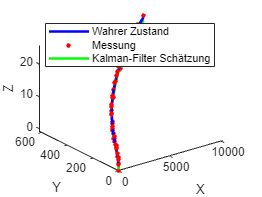

% Parameter des Systems
dt = 1;                % Abtastzeit
A = [1 dt dt^2/2; 0 1 dt; 0 0 1];       % Zustandsübergangsmatrix
B = [dt^3/6; dt^2/2; dt];      % Steuerungsmatrix (Beschleunigung)
C = eye(3);             % Messmatrix (direkte Messung von X, Y, Z)
Q = diag([0.01, 0.01, 0.1]);   % Prozessrauschkovarianz
R = diag([1, 1, 1]);                 % Messrauschkovarianz

% Simulierte Daten
T = 50;               % Anzahl der Zeitschritte
true_pos = zeros(3, T);
measured_pos = zeros(3, T);
velocity = [1; 0; 0];      % Geschwindigkeitsvektor (konstant in x-Richtung)
acceleration = [0; 0; 0.5]; % Beschleunigungsvektor (konstant in z-Richtung)
for t = 1:T
    true_pos(:,t) = A * (true_pos(:, max(t-1,1))) + B .* acceleration;    % Zustandsübergang
    measured_pos(:,t) = true_pos(:,t) + sqrt(R) * randn(3, 1);        % Messung
end

% Initialisierung
x = zeros(3, T);       % Zustandsschätzung
P = zeros(3, 3, T);    % Zustandskovarianzschätzung

% Schätzung mit Kalman-Filter
for t = 1:T
    % Vorhersage
    if t == 1
        x_pred = [0; 0; 0];
        P_pred = eye(3);
    else
        x_pred = A * x(:,t-1);
        P_pred = A * P(:,:,t-1) * A' + Q;
    end
    
    % Korrektur
    K = P_pred * C' / (C * P_pred * C' + R);
    x(:,t) = x_pred + K * (measured_pos(:,t) - C * x_pred);
    P(:,:,t) = (eye(3) - K * C) * P_pred;
end

% Ergebnisse anzeigen
figure;
hold on;
plot3(true_pos(1,:), true_pos(2,:), true_pos(3,:), 'b-', 'LineWidth', 2);
plot3(measured_pos(1,:), measured_pos(2,:), measured_pos(3,:), 'r.', 'MarkerSize', 10);
plot3(x(1,:), x(2,:), x(3,:), 'g-', 'LineWidth', 2);
legend('Wahrer Zustand', 'Messung', 'Kalman-Filter Schätzung');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);